## E1

## a)

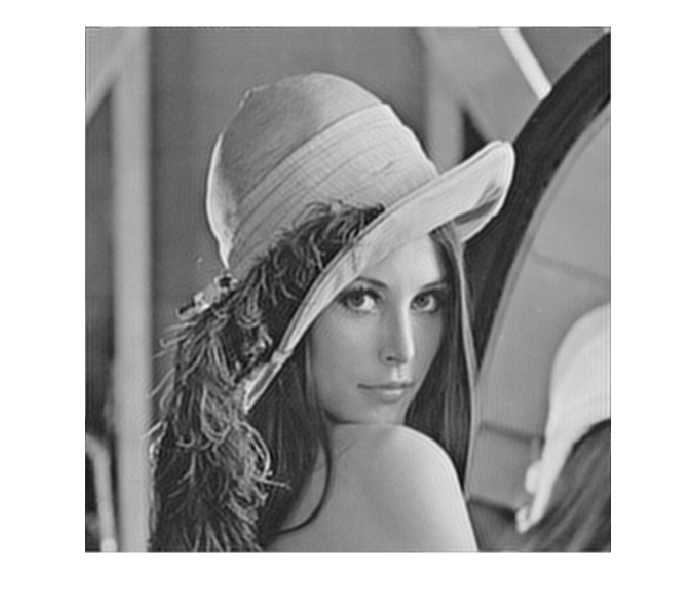

clear; clc;
% Compute 2D DFT of an image
f = double(imread('Lena.bmp')); % read an image
[H, W ] = size(f); % image size
% Step 1: Create the ideal low-pass filter
[v, u] = dftuv(H, W); % Create frequency grid
Hd = zeros(H, W); % Allocate and initialize ideal low-pass filter
D0 = 0.2; % cut-off frequency
% Find (u,v) pairs where distance < cut-off frequency
idx = sqrt(u.^2 + v.^2) <= D0; 
% For these (u,v) pairs, set frequency response to 1
Hd(idx) = 1; 
% Step 2: Perform filtering in the frequency domain
F = fft2(f); % Compute 2-D DFT of input image
G = F .* Hd; % 2-D DFT of output image
g = real(ifft2(G)); % Inverse DFT
g = uint8(g);

imshow(g); % Show output

## b)

% Read the image
f = double(imread('Lena-gaussian-noise.bmp'));

% Compute the maximum value of D0
[M, N] = size(f);
Dmax = sqrt((M/2)^2 + (N/2)^2)

Dmax = 362.0387

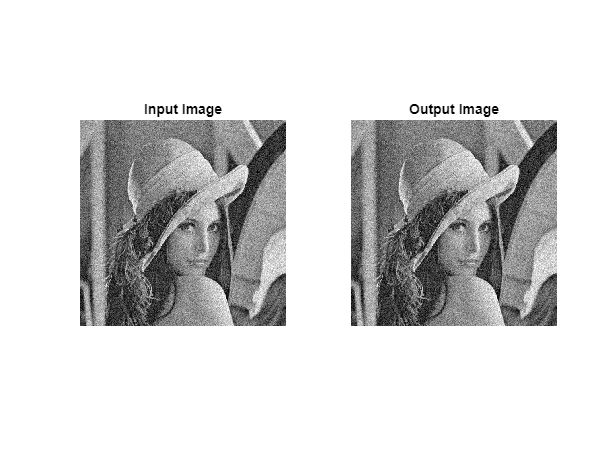


% Determine the cut-off frequency
% D0 = 50;
D0 = 200;

% Create the Butterworth low-pass filter
n = 3; % order of the filter
H = 1 ./ (1 + (sqrt(2) - 1) * (dftuv(size(f, 1), size(f, 2)) / D0).^(2*n));

% Apply the filter in the frequency domain
F = fft2(f);
G = F .* H;

% Compute the output image
g = real(ifft2(G));

% Display the input and output images side by side
figure;
subplot(1,2,1);
imshow(uint8(f));
title('Input Image');
subplot(1,2,2);
imshow(uint8(g));
title('Output Image');

## c)

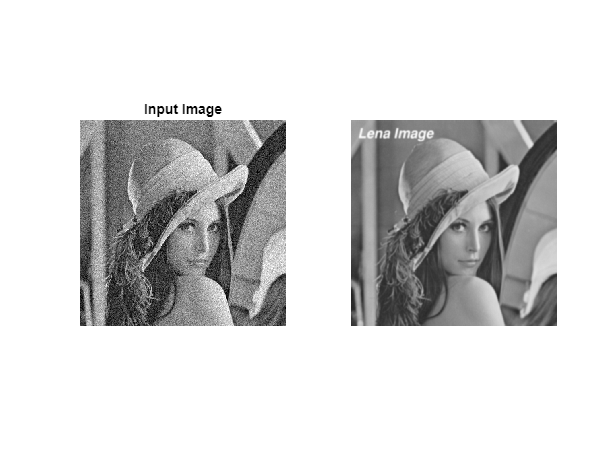

% Read the image
f = double(imread('Lena-blur.bmp'));

% Define the parameters
k = 2;
delta = 0.001;

% Create the Gaussian low-pass filter
D0 = 50;
Hg = exp(-(dftuv(size(f, 1), size(f, 2)).^2) / (2 * D0^2));

% Create the high-boost filter
Hsharpen = 1 + k * (1 - Hg);

% Apply the filter in the frequency domain
F = fft2(f);
G = Hsharpen .* F;

% Compute the output image
g = real(ifft2(G));

% Add the original image to the output image to enhance the high-frequency components
g = f + delta * g;

% Display the output image
imshow(uint8(g));